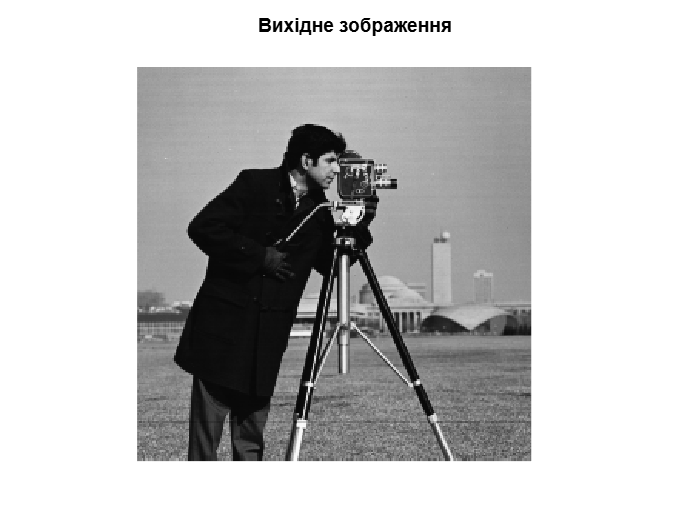

clear;
close all;

I = imread('cameraman.tif');
figure;
imshow(I);
title('Вихідне зображення');

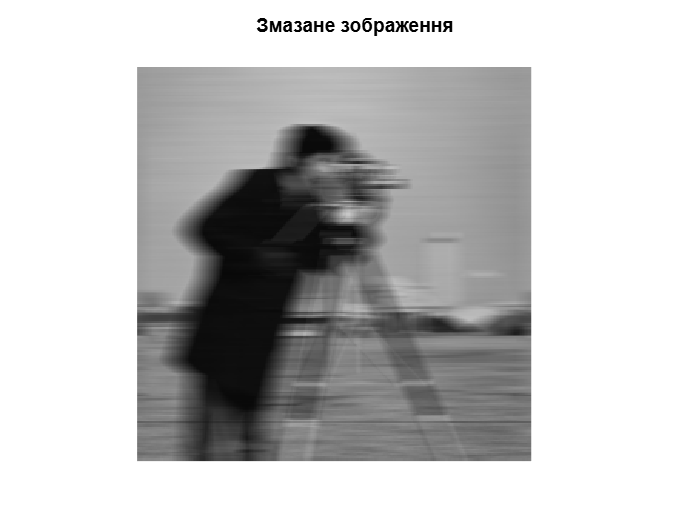


%% 2. Перекручення зображення (змазання через рух)
LEN = 21;      % Довжина зсуву в пікселях
THETA = 0;     % Кут руху (0 - горизонтальний)
PSF = fspecial('motion', LEN, THETA); % Створення фільтра перекручення
blurred = imfilter(I, PSF, 'conv', 'circular');

figure;
imshow(blurred);
title('Змазане зображення');

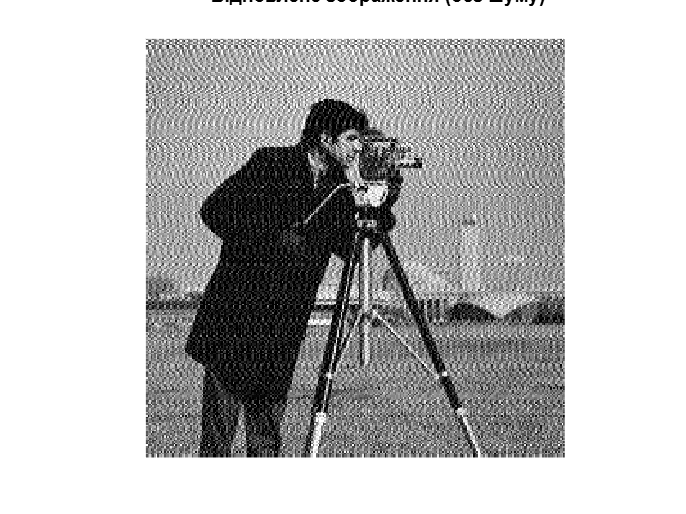


%% 3. Відновлення зображення (без шуму)
SNR_no_noise = 0; % Відношення сигнал/шум (0 = шум відсутній)
restored = deconvwnr(blurred, PSF, SNR_no_noise);

figure;
imshow(restored);
title('Відновлене зображення (без шуму)');

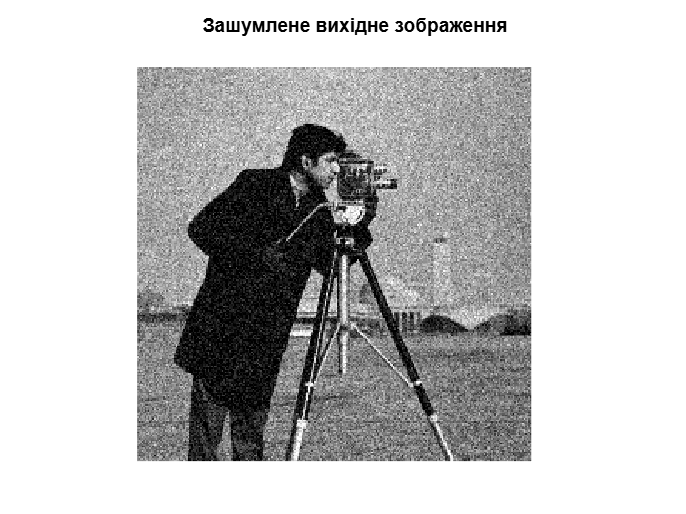


%% 4. Додавання шуму до вихідного зображення
noisy_I = imnoise(I, 'gaussian', 0, 0.01); % Гаусівський шум з дисперсією 0.01

figure;
imshow(noisy_I);
title('Зашумлене вихідне зображення');

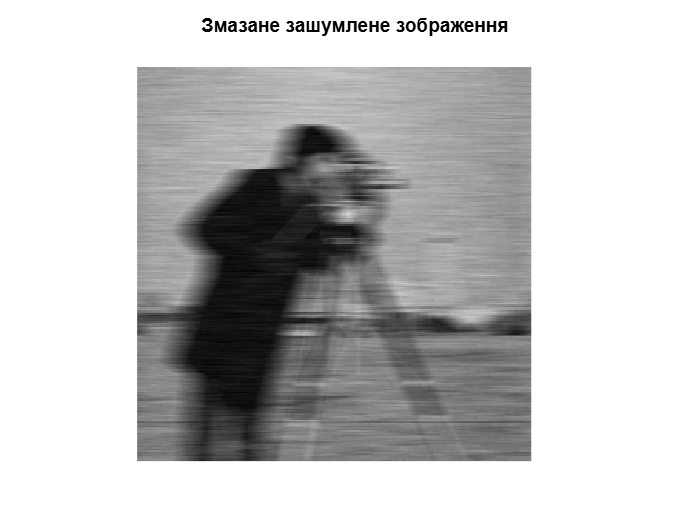


%% 5. Перекручення зашумленого зображення
blurred_noisy = imfilter(noisy_I, PSF, 'conv', 'circular');

figure;
imshow(blurred_noisy);
title('Змазане зашумлене зображення');

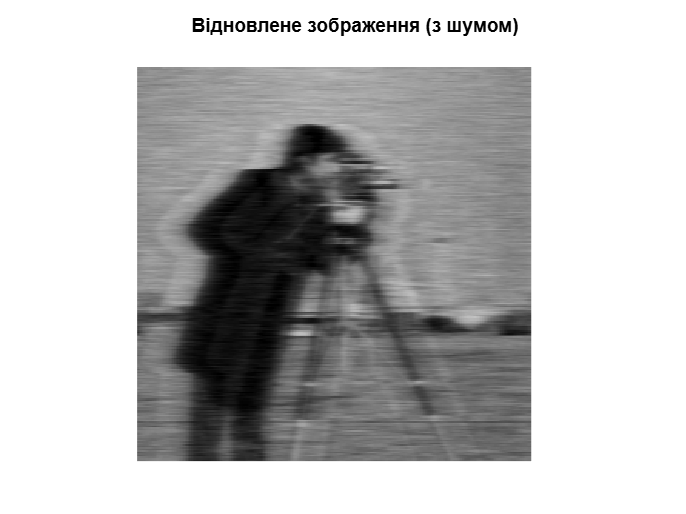


%% 6. Відновлення зашумленого зображення
SNR_with_noise = 0.1; % Емпіричне значення SNR (можна змінювати)
restored_noisy = deconvwnr(blurred_noisy, PSF, SNR_with_noise);

figure;
imshow(restored_noisy);
title('Відновлене зображення (з шумом)');